## IE3032/BE3022 - Lección 5

Podemos emplear directamente la definición abstacta de un sistema discreto para evaluar cuál es el efecto que tiene sobre una señal. Por ejemplo, consideremos que el siguiente sinusoide:

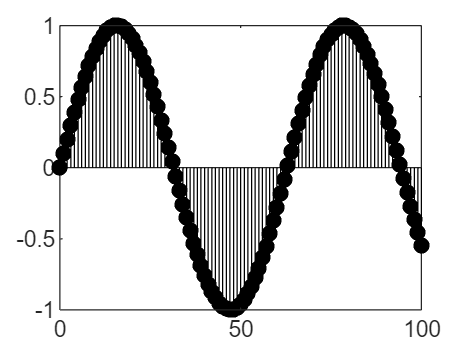

n = 0:100;
x = sin(0.1*n);

figure;
stem(n, x, 'k', 'filled');

se procesa mediante el sistema $y[n]=\mathcal{H}\{x[n]\}=x^2[n]$. Podemos emplear directamente la definición para obtener:

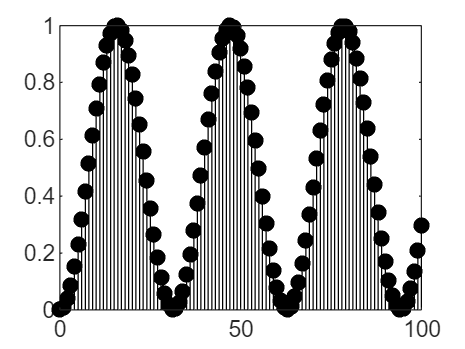

y = x.^2;

figure;
stem(n, y, 'k', 'filled');

Recordemos que también tenemos el "visor" del dominio de frecuencia, por lo que también podríamos evaluar cuál fue el efecto del sistema en frecuencia:

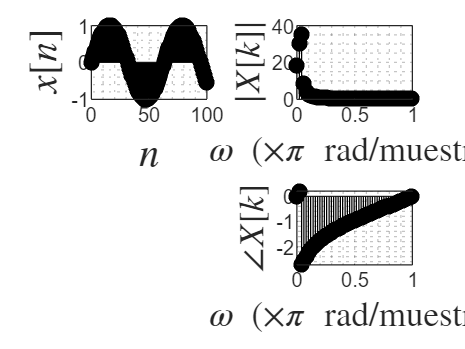

spectrum(x, 'stem'); % Nueva función auxiliar para visualizar

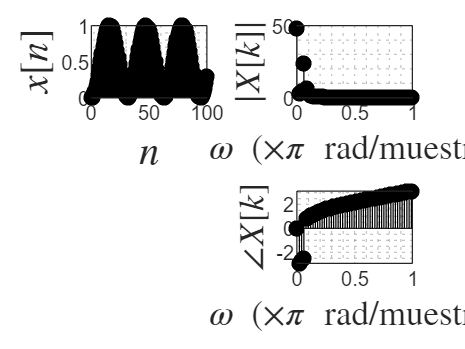

spectrum(y, 'stem'); % el espectro. Notar que sólo se grafica

                     % de 0 a pi.

Podemos evidenciar aún más claramente el efecto del sistema si lo aplicamos a una señal con la que podamos interactuar, como audio por ejemplo:

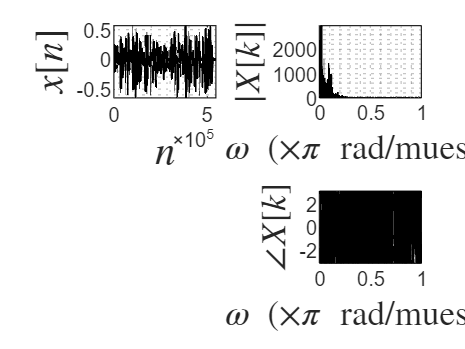

[x, fs] = audioread('riff.wav');
% sound(x, fs);
spectrum(x, 'plot'); % la función permite visualizar "uniendo los puntos" también

En este caso, el resultado de aplicar el sistema anterior resulta ser:

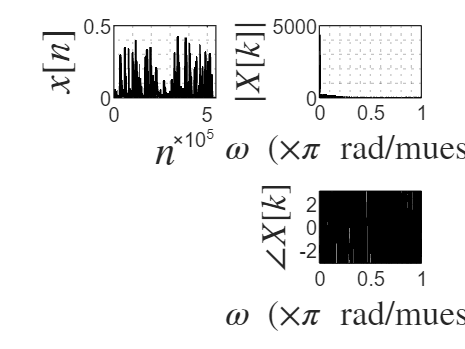

y = x.^2;
% sound(y, fs);
spectrum(y, 'plot');

Otros efectos interesantes pueden ser:

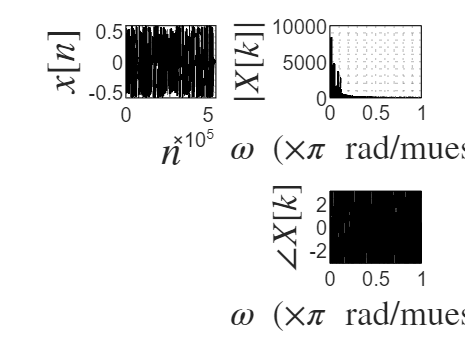

% Distorsión
y = 0.4*atan(15*x);
% sound(y, fs);
spectrum(y, 'plot');

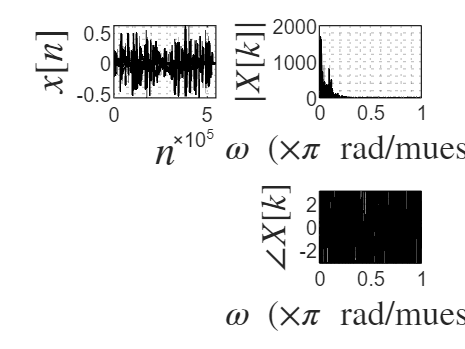


% Phaser
n = (1:length(x))';
y = x .* cos((2*pi*5/44100)*n);
% sound(y, fs);
spectrum(y, 'plot');

También podemos emplear MATLAB para evaluar linealidad e invarianza en el tiempo de un sistema, evitando las demostraciones algebráicas **(páginas 10 y 13)**.

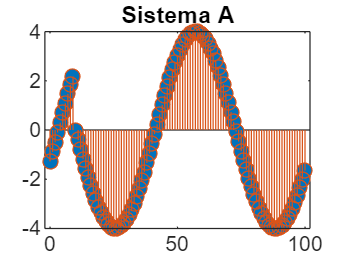

% En este caso definiremos los sistemas como funciones anónimas de MATLAB.
% Las podemos modificar.
k = 10;
sistemaA = @(x) 2*circshift(x, k);  % H_A: 2x[(n-k) mod N]

sistemaB = @(x) x.^2;  % H_B: (x[n])^2

n = 0:100;
x = sin(0.1*n);  % x[n]

% ---------- Homogeneidad ----------
% Sistema A
ya1 = sistemaA(x);   % H_A{x[n]}
alpha_ya1 = -2*ya1;
xa0 = -2*x;
ya0 = sistemaA(xa0);
figure;
stem(n, ya0, 'filled');
hold on;
stem(n, alpha_ya1);
hold off;
title('Sistema A');

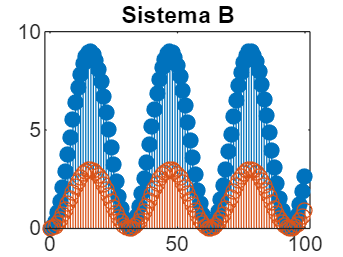


% Sistema B
yb1 = sistemaB(x);   % H_B{x[n]}
alpha_yb1 = 3*yb1;
xb0 = 3*x;
yb0 = sistemaB(xb0);
figure;
stem(n, yb0, 'filled');
hold on;
stem(n, alpha_yb1);
hold off;
title('Sistema B');

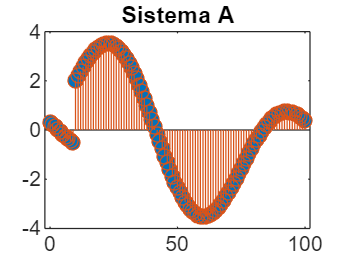



% ---------- Superposición ----------
x1 = x;
x2 = cos(0.05*n);
x3 = x1 + x2;

% Sistema A
y1 = ya1;
y2 = sistemaA(x2);
y3 = sistemaA(x3);
y1py2 = y1 + y2;
figure;
stem(n, y3, 'filled');
hold on;
stem(n, y1py2);
hold off;
title('Sistema A');

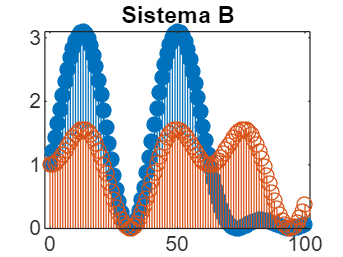


% Sistema B
y1 = yb1;
y2 = sistemaB(x2);
y3 = sistemaB(x3);
y1py2 = y1 + y2;
figure;
stem(n, y3, 'filled');
hold on;
stem(n, y1py2);
hold off;
title('Sistema B');

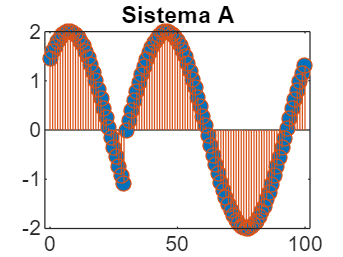



% ---------- Invarianza en el tiempo (pág. 13) ----------
m = 20;

% Sistema A
xa0 = circshift(x, m);  % x[(n-m) mod N]
ya0 = sistemaA(xa0);
yatau = circshift(ya1, m);
figure;
stem(n, ya0, 'filled');
hold on;
stem(n, yatau);
hold off;
title('Sistema A');

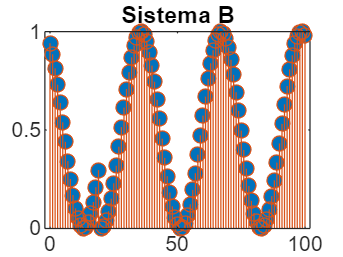


% Sistema B
xb0 = circshift(x, m);  % x[(n-m) mod N]
yb0 = sistemaB(xb0);
ybtau = circshift(yb1, m);
figure;
stem(n, yb0, 'filled');
hold on;
stem(n, ybtau);
hold off;
title('Sistema B');